# HW 10

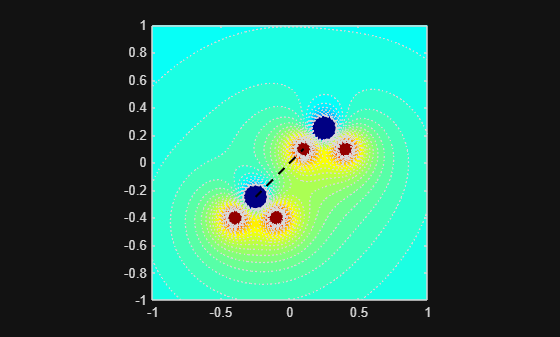

clear all
%%%%% calculating electrostatic potential around charge
Eps0 = 8.8*10^-12;
K = 1/(4*pi*Eps0);
% K=8.99*10^9; % constant 1/(4*pi*Eps0), where Eps0= 8.85E-12 Farad per meter (F/m)
e0=1.6E-19;  % Charge of an electron
% create mesh
g=-1:0.01:1;
% create 2D mesh grid
[xg,yg]=meshgrid(g);
% inside charge set constant value
d_h = 0.05; % the "radius" of charge H
d_o = d_h*1.8; % according to Quora forum pages the O atom is 1.8-times bigger than the H atom

%% H2O_1
%%%%% charge 1
q1=-1*e0; % (+1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=0-0.25; % x coordinate of charge
yp=0-0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V1=q1*K./R; % V=e/(4*pi*eps*r)
idx1=(R<d_o); % grids inside the radious
V1max = K*q1 / d_o;

%%%%% charge 2
q2=1*e0; % (-1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=0.15-0.25; % x coordinate of charge
yp=-0.15-0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V2=q2*K./R; % V=e/(4*pi*eps*r)
idx2=(R<d_h); % grids inside the radious
V2max = K*q2 / d_h;

%%%%% charge 3
q3=1*e0; % (-1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=-0.15-0.25; % x coordinate of charge
yp=-0.15-0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V3=q3*K./R; % V=e/(4*pi*eps*r)
idx3=(R<d_h); % grids inside the radious
V3max = K*q3 / d_h;

%% H2O_2
%%%%% charge 1
q4=-1*e0; % (+1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=0+0.25; % x coordinate of charge
yp=0+0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V4=q4*K./R; % V=e/(4*pi*eps*r)
idx4=(R<d_o); % grids inside the radious
V4max = K*q4 / d_o;

%%%%% charge 2
q5=1*e0; % (-1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=0.15+0.25; % x coordinate of charge
yp=-0.15+0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V5=q5*K./R; % V=e/(4*pi*eps*r)
idx5=(R<d_h); % grids inside the radious
V5max = K*q5 / d_h;

%%%%% charge 3
q6=1*e0; % (-1) Electric charge can exist only as an integral multiple of charge of an electron
% The Possible values of electric charge are q = ± 1e0; ± 2e0; ± 3e0...
xp=-0.15+0.25; % x coordinate of charge
yp=-0.15+0.25; % y coordinate of charge
xi=xg-xp; % displacement between grid point and charge, X component
yi=yg-yp; % displacement between grid point and charge, Y component
R=sqrt(xi.^2 + yi.^2); %
V6=q6*K./R; % V=e/(4*pi*eps*r)
idx6=(R<d_h); % grids inside the radious
V6max = K*q6 / d_h;

%% sum (contribution of all chrages) and find max value 
V=V1+V2+V3+V4+V5+V6; % contribution of both chrages !!!!
V(idx1)=V1max; % set constant value inside the charge
V(idx2)=V2max; % set constant value inside the charge
V(idx3)=V3max; % set constant value inside the charge
V(idx4)=V4max; % set constant value inside the charge
V(idx5)=V5max; % set constant value inside the charge
V(idx6)=V6max; % set constant value inside the charge

% Coordinates of oxygen and hydrogen atoms
% Molecule 1 (O atom)
x_O1 = 0 - 0.25; % x-coordinate of oxygen atom in molecule 1
y_O1 = 0 - 0.25; % y-coordinate of oxygen atom in molecule 1

x_H2_2 = -0.15 + 0.25; % x-coordinate of second hydrogen atom in molecule 2
y_H2_2 = -0.15 + 0.25; % y-coordinate of second hydrogen atom in molecule 2

% Calculate distances between O1 and the H atoms of molecule 2
d_H2_2 = sqrt((x_H2_2 - x_O1)^2 + (y_H2_2 - y_O1)^2); % Distance to second H atom

x_hbond = [x_O1, x_H2_2];
y_hbond = [y_O1, y_H2_2];

figure
%contourf(xg,yg,V)
contourf(xg,yg,V,50,':','LineWidth',1) % filled contour plot containing the isolines of matrix Z
colormap(jet)
hold on;

plot(x_hbond, y_hbond, 'k--', 'LineWidth', 1.5); % H-bond

% If black lines represending H-bond are hard to see use one of the these:
%plot(x_hbond, y_hbond, 'w--', 'LineWidth', 1.5); % H-bond
%plot(x_hbond, y_hbond, 'g--', 'LineWidth', 1.5); % H-bond
%plot(x_hbond, y_hbond, 'r--', 'LineWidth', 1.5); % H-bond

hold off;

%text(0,0,'-','FontSize',20,'Color','w','HorizontalAlignment','center','VerticalAlignment','middle')
%text(0.3,-0.3,'+','FontSize',20,'Color','w','HorizontalAlignment','center','VerticalAlignment','middle')
%text(-0.3,-0.3,'+','FontSize',20,'Color','w','HorizontalAlignment','center','VerticalAlignment','middle')

ax=gca;
axis(ax,'equal')





% saveas(gcf,'Figure_charge2.png')

%figure
%s=surf(xg,yg,V); % surface
%s.EdgeColor = 'none';
